## Parareal algorithm for an ODE

clear all; close all; clc;

### Set parameters of the ODE

% params
T = 14.0;
y0 = 0.1;
N_coarse = 20;
dT = T/N_coarse;
dt = 0.002;
N_fine = floor(dT/dt)

N_fine = 349

% N_fine = 600;

### Solve the system of ODEs

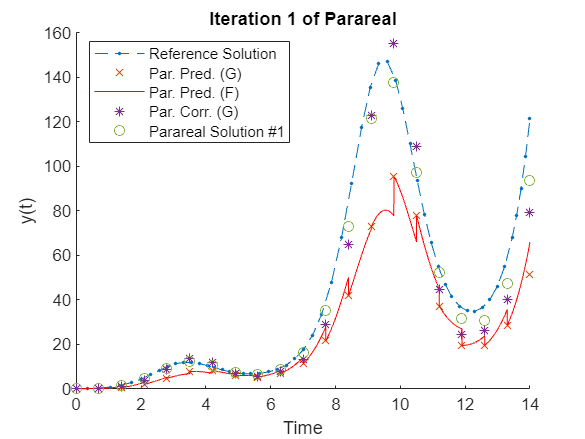

increment at iteration 1: 91.7394


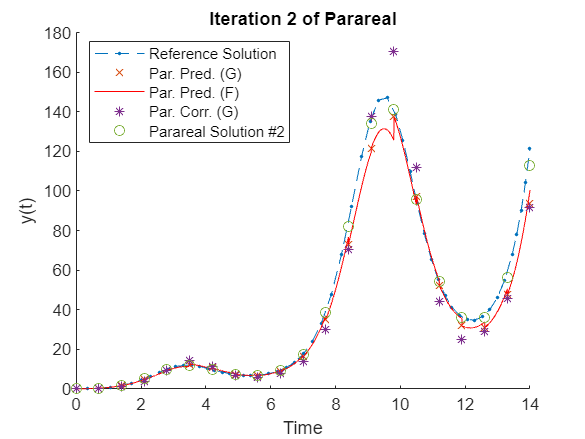

increment at iteration 2: 27.8264


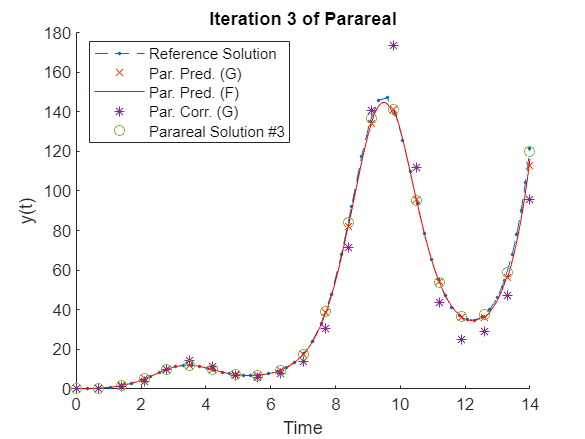

increment at iteration 3: 8.2746


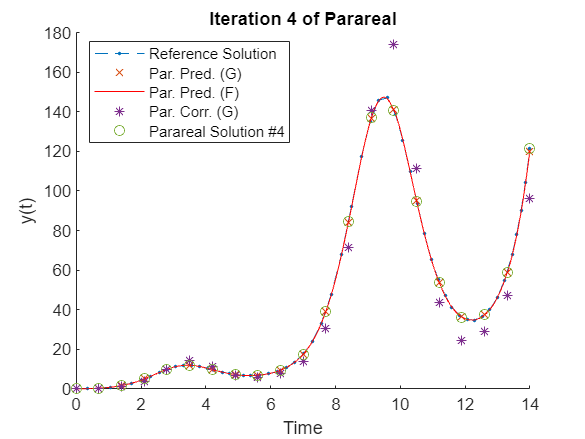

increment at iteration 4: 1.5542


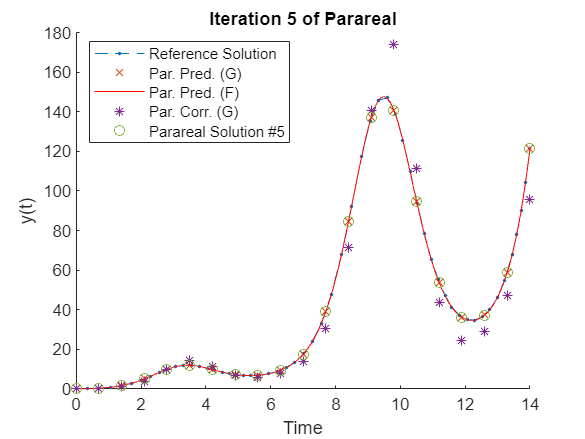

increment at iteration 5: 0.21805


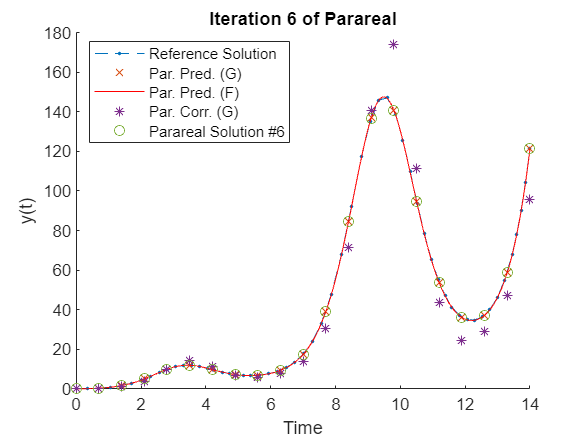

increment at iteration 6: 0.10218


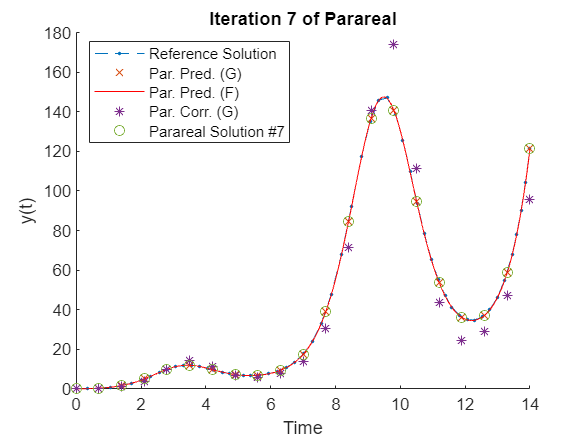

increment at iteration 7: 0.032736


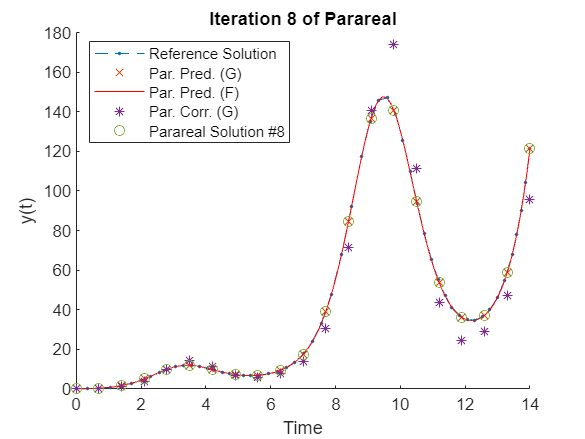

increment at iteration 8: 0.0059961


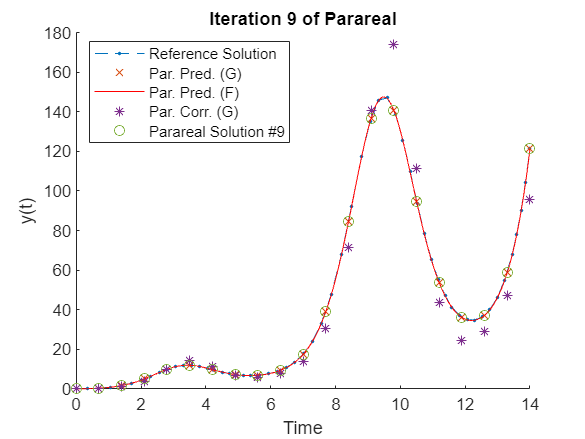

increment at iteration 9: 0.00046608
Parareal converged at iteration 9


% reference sol
tic
[t_ref, y_ref] = ode45(@(t, y) fun(t, y), [0, T], y0);
time_ref = toc;

% sequential sol (only coarse solver)
tic
steps = N_coarse * N_fine;
y_seq = sequential(T, y0, steps);
time_seq = toc;

% parareal
tic
[t_par, y_par] = parareal(0, T, y0, N_coarse, N_fine, 1, t_ref, y_ref);

time_par = toc;

% % parareal_opt
% tic
% [t_par_opt, y_par_opt] = parareal_opt(T, y0, N_coarse, N_fine);
% time_par_opt = toc;

### Display results

err = abs(y_ref(end) - y_par(end));
disp(['error of parareal: ' num2str(err)])

error of parareal: 0.14787


err = abs(y_ref(end) - y_seq);
disp(['error of sequential: ' num2str(err)])

error of sequential: 0.14754


% err = abs(y_ref(end) - y_par_opt(end));
% disp(['error of parareal_opt: ' num2str(err)])

disp(['time_ref: ' num2str(time_ref)])

time_ref: 0.081084


disp(['time_seq: ' num2str(time_seq)])

time_seq: 0.014567


disp(['time_par: ' num2str(time_par)])

time_par: 3.0058


% disp(['time_par_opt: ' num2str(time_par_opt)])

### Plots

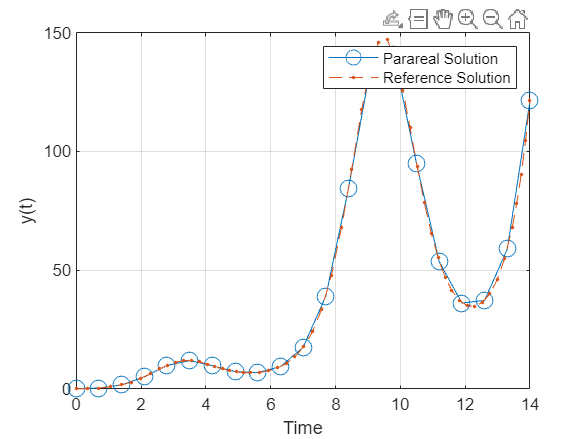

% plot
plot(t_par, y_par, 'o-', 'MarkerSize', 10, 'DisplayName', 'Parareal Solution');
hold on;
plot(t_ref, y_ref, '.--', 'DisplayName', 'Reference Solution');
hold off;
xlabel('Time');
ylabel('y(t)');
legend();
grid on;